#  ECSE 343: Numerical Methods in Engineering

#  Assignment 3

Due Date:  21st March 2024

Student Name: Karen Chen Lai

Student ID:    261107674

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with a **PDF** copy of this file.

Note: You can write the function in the appendix section using the provided stencils.

**In this assignment you may use the backslash operator, '\' to solve systems such as Ax=b for questions involving solutions of nonlinear equations only.**

clear all;

## Question 1:  Linear Regression Revisited

Suppose we are given the following equations,

$M\;\mathit{\mathbf{a}}=\mathit{\mathbf{y}}$,  $M \in \mathbb{R}^{m\times n}$ with $m>n$

We want to fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


You are given t›he following data, your data is loaded and plotted in the cell below. Make sure the provided data files are present in the same directory as this script.

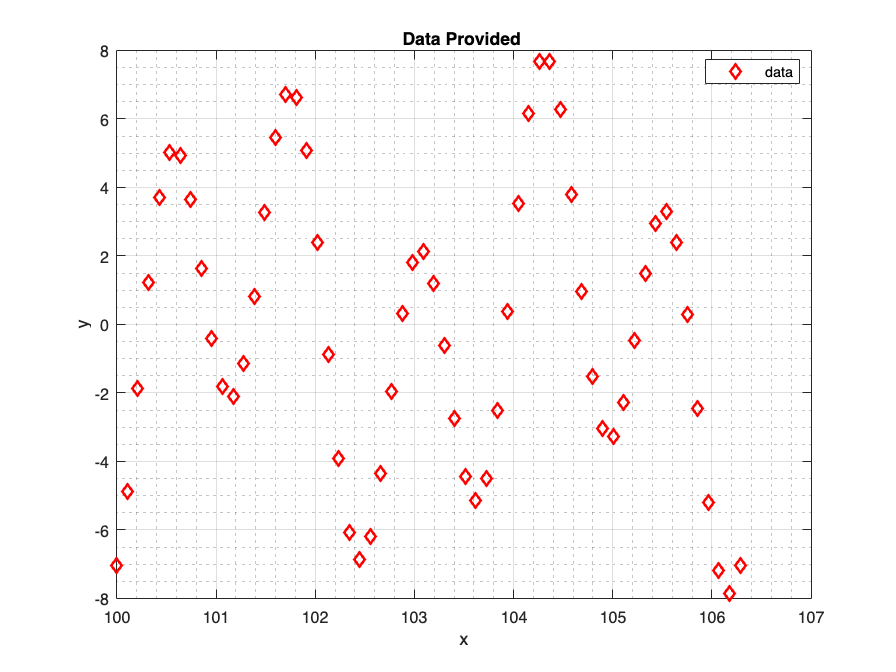

load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 3/Asst3_data_Q1a.mat'); % load the data 

x = x_given;
y = y_given; 

figure
plot(x,y, 'rd',"LineWidth",2,"DisplayName",'data')
legend("Location","best") 
xlabel('x') ;ylabel('y')
grid on; grid minor
title('Data Provided ')

a. Using the code you wrote in Assignment 2, construct the Vandermonde matrix, M, for the data provided. Suppose we choose to model the provided data with a polynomial of **degree 17**. Using the cell below, fit a polynomial of degree 17**, **i.e. $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$.  You can use the MATLAB's QR decomposition function to find the polynomial coefficients.

% Assuming x and y are your data vectors and deg is the degree of the polynomial:
deg = 17;

M = PolynomialMatrix(x, deg); % vandermonde matrix

[Q, R] = qr(M, 0);
b = Q' * y;
Ar = backward_sub(R, b);

Now that you have obtained the coefficients, $a_i,  \;\;0\leq i \leq17$ , for the polynomial model, $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$. Since the input data was linearly spaced between 100 to $100+2\pi \;$, you can use 200 linearly spaced points to test the performance of your model.

In the cell below, use the data you used to build the model as reference to test the performance of the obtained model by plotting it on the same plot.  Make sure your plots axis are labeled and the plots must contain a title and a legend. 

Hint: You can use the code you used in Assignment 2.

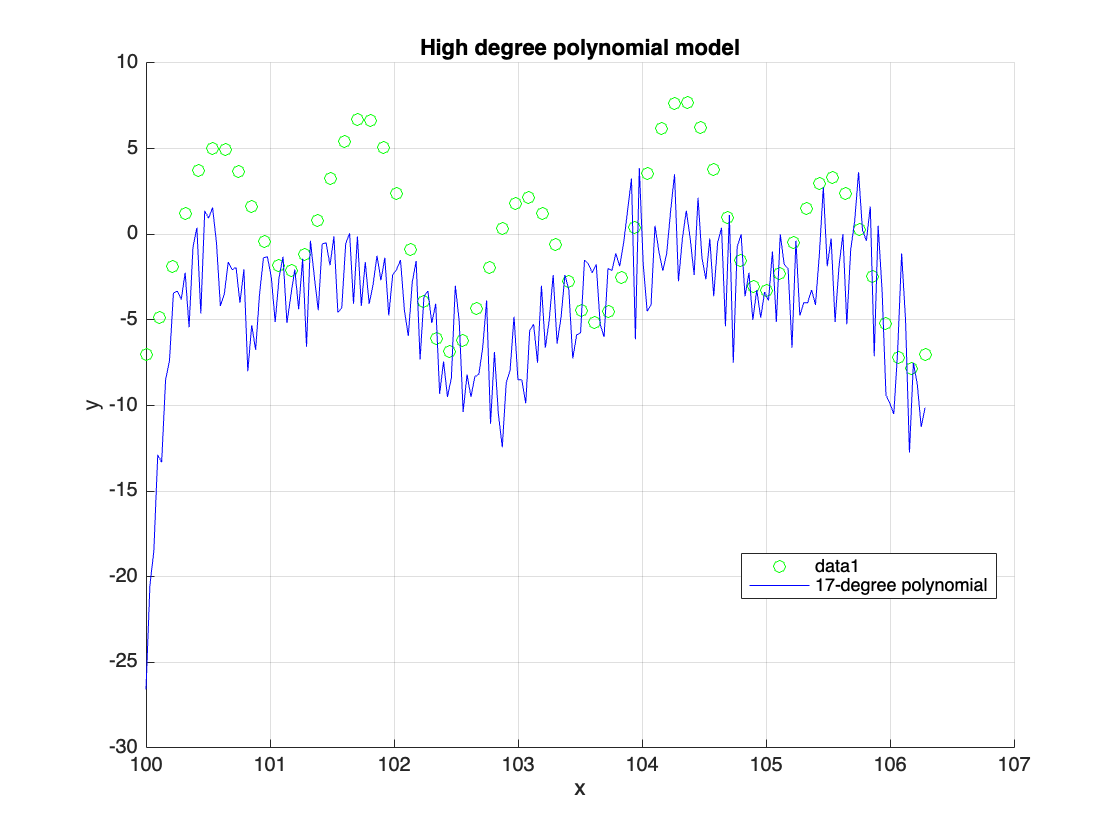

%----------------------------------------------------------------
x_test = linspace(100+0,100+2*pi,200);  % generate test data 
x_test =x_test';
%----------------------------------------------------------------

r = zeros(length(x_test),1);
   powers = 0:deg;
   for indx = 1:length(powers)
       r = r + Ar(indx)*x_test.^powers(indx);   
   end

figure;
hold on;
plot(x,y,'go');
plot(x_test, r, 'b-', 'DisplayName', sprintf('17-degree polynomial'));
legend('Location', 'best');
legend('show');
title('High degree polynomial model');
ylabel('y');
xlabel('x');
grid on;
hold off;

Is the model you obtained accurate? Suggest what you will do to improve the performance of the model.

*% The model seems to be overfitting because of fluctuations of the 17th degree polynomial curve respect to the data points. In order to improve the performance of the model, something that i can do regularization to reduce the overfitting, try reducing the polynomial degree since high-degree polynomial has high chance of overfitting, and try using different algorithms instead of ordinary least square.*

b. If the polynomial model you obtained in part a is not accurate, make appropriate changes to data to fit a polynomial model of order 17 shown in part a. Use the cell below to write your code. You can use the MATLAB's QR decomposition function to find the polynomial coefficients.

Plot the obtained model along with the data used to build the model. Make sure your plots axis are labeled and the plots must contain a title and a legend. 

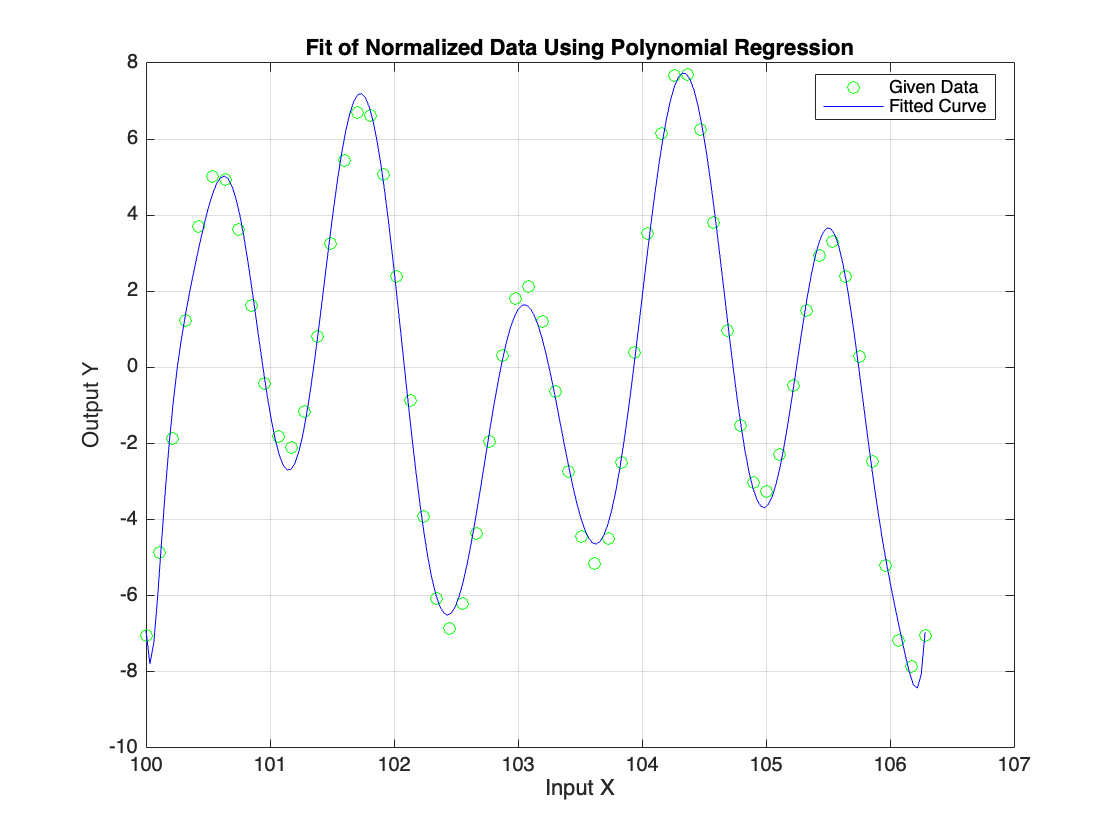

data_lower_bound = min(x_given);
data_upper_bound = max(x_given);

normalized_input = (x_given - data_lower_bound) / (data_upper_bound - data_lower_bound);

polynomial_order = 17;
polynomial_matrix = zeros(numel(normalized_input), polynomial_order + 1);

for idx = 0:polynomial_order % Vandermonde matrix
    polynomial_matrix(:, idx+1) = normalized_input.^idx;
end
%QR decomposition
[orthogonal_matrix, upper_triangular_matrix] = qr(polynomial_matrix, 0) ;

coefficients = upper_triangular_matrix \ (orthogonal_matrix' * y_given);

test_points_normalized = linspace(0, 1, 200)';
predicted_output = zeros( size(test_points_normalized) ) ;

for idx = 0:polynomial_order
    predicted_output = predicted_output + coefficients(idx+1) * test_points_normalized.^idx ;
end

test_points = test_points_normalized * (data_upper_bound - data_lower_bound) + data_lower_bound ;

figure;
plot(x_given, y_given, 'go', 'DisplayName', 'Given Data');
hold on;
plot(test_points, predicted_output, 'b-', 'DisplayName', 'Fitted Curve');
hold off;
ylabel('Output Y'); 
xlabel('Input X');
legend('Location', 'best');
title('Fit of Normalized Data Using Polynomial Regression');
grid on; 

Write a brief summary on how you obtained the correct model.

*% write your comments here for question 1b*

    This method involved normalizing the data to fall between 0 and 1 before the polynomial model was fitted. When fitting high-degree polynomials, normalizing the data can assist reduce numerical problems that may occur, particularly if the original data has a wide range. By doing this, the fitting procedure's numerical stability is increased, which might result in a more accurate model. The model was assessed using a set of test points that were likewise normalized before being projected back to the original scale for visualization in order to determine the polynomial coefficients. This guarantees a meaningful and aesthetically pleasing contrast between the actual data and the model forecast.

c. In this part use the data set loaded in the cell below and repeat part b, fit a polynomial of degree 17, i.e. $p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$ to the provided data. Comment on your results. Plot the obtained model along with the data used to build the model. Make sure your plots axis are labeled and the plots must contain a title and a legend. 

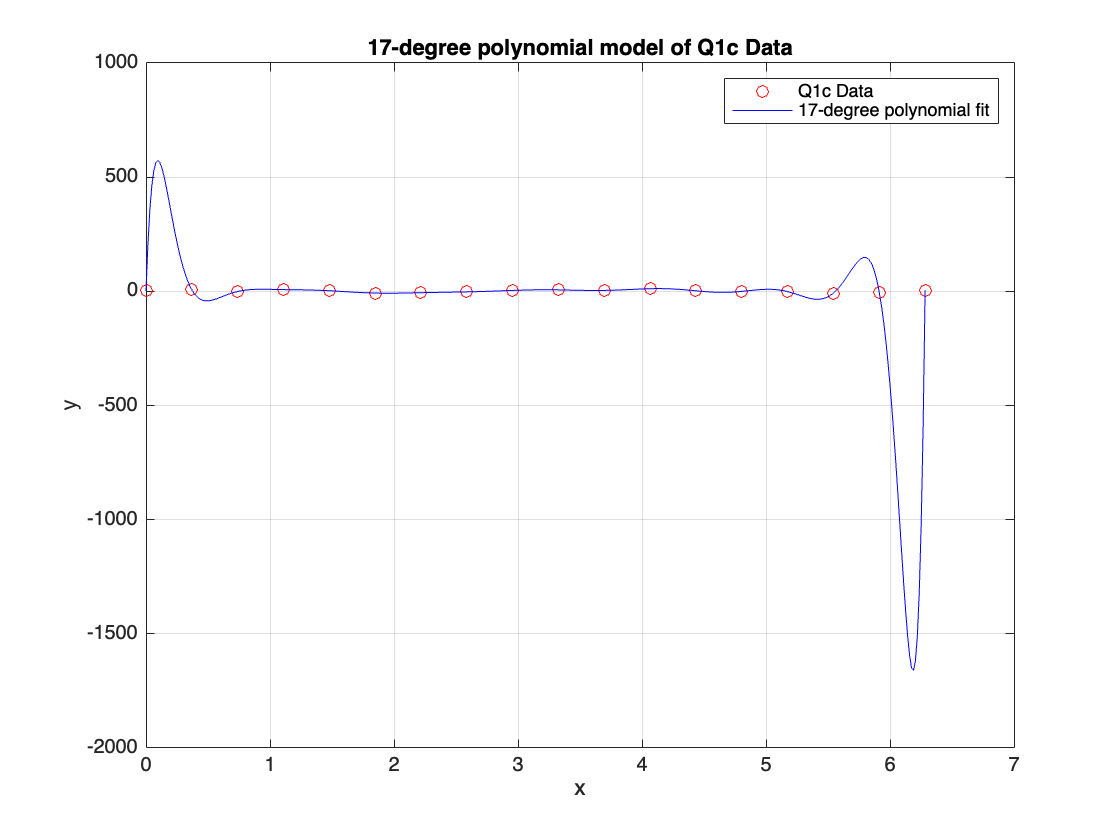

load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 3/Asst3_data_Q1c.mat');

x = x_given; % input data
y = y_given; % output data
 
deg = 17;
M = PolynomialMatrix(x, deg);
[Q, R] = qr(M, 0);
qT = Q' * y;
bU = qT(1:18) ;
RU = R(1:18, 1:18);
Ar = backward_sub(RU, bU) ;

xv = linspace(min(x), max(x), 400);
px = polyval(flipud(Ar), xv);

figure;
plot(x, y, 'ro', 'DisplayName', 'Q1c Data'); 
hold on;
plot(xv, px, 'b-', 'DisplayName', '17-degree polynomial fit'); 
title('17-degree polynomial model of Q1c Data');
ylabel('y');
xlabel('x');
legend('show');
grid on;

COMMENT: 

    The plotted result suggests that the polynomial fit is not performing as predicted. When working with high-degree polynomials, the polynomial function tends to diverge significantly outside of a specific range of x values, which is a telltale indicator of overfitting. Because of the high degree of the polynomial and the sensitivity of high-degree components to little fluctuations in the data, this frequently occurs close to the borders of the data set.

d. For this part your task is to design a Tikhnov Regularisation based algorithm to fit the data using the polynomial of degree 17. Your algorithm must be optimised for **accuracy.**  Use the cell below to compute the coefficients of $17^{th}$ degree polynomial.  Use trial and error to choose the value of regularisation constant, $\lambda$.

Plot the obtained model along with the data used to build the model.

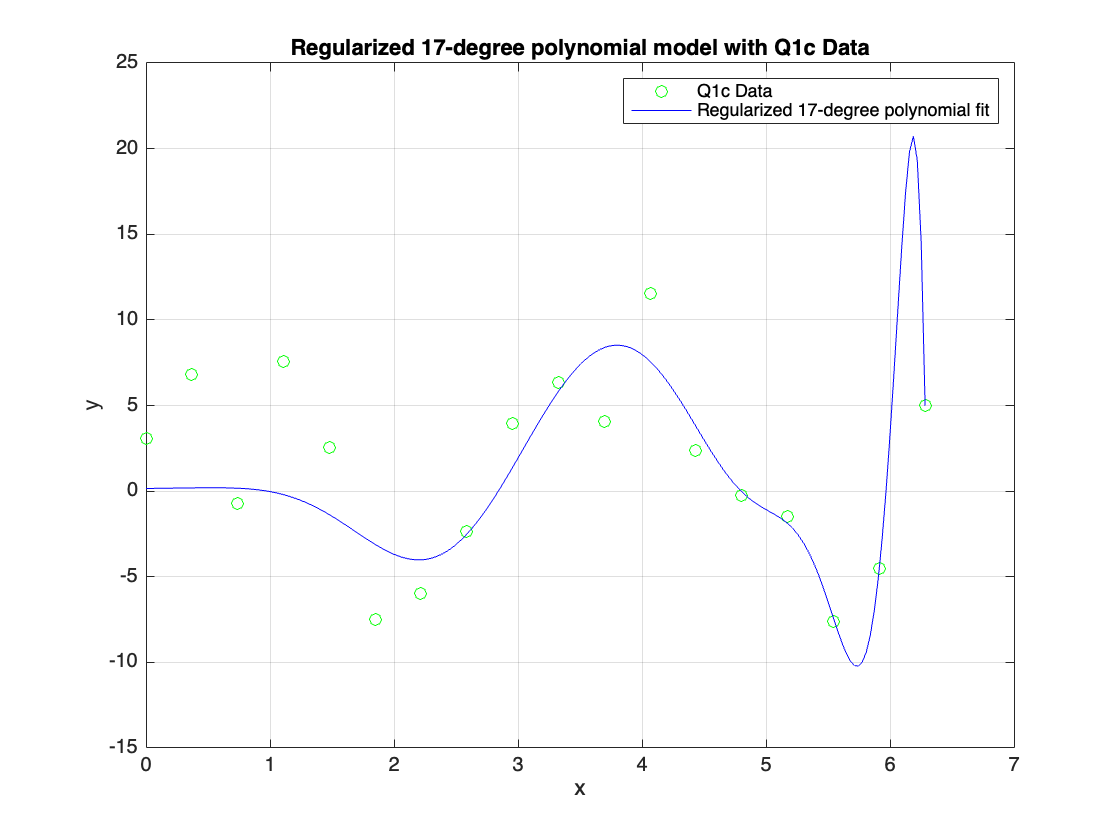

l = 100; % lambda adjusted

M_augmented = [M; sqrt(l)*eye(18)];
y_augmented = [y; zeros(18, 1)];
[Q_augmented, R_augmented] = qr(M_augmented, 0) ;

qT_augmented = Q_augmented' * y_augmented;
RU_augmented = R_augmented(1:18, 1:18);
bU_augmented = qT_augmented(1:18);
Ar_augmented = backward_sub(RU_augmented, bU_augmented) ;

xv = linspace(min(x), max(x), 200);
px_augmented = polyval(flipud(Ar_augmented), xv);% regularized polynomial at the test points

figure;
plot(x, y, 'go', 'DisplayName', 'Q1c Data'); 
hold on;
title('Regularized 17-degree polynomial model with Q1c Data');
plot(xv, px_augmented, 'b-', 'DisplayName', 'Regularized 17-degree polynomial fit'); 
ylabel('y');
xlabel('x');
legend('show');
grid on;
hold off;

e. Using the cell below, plots the models obtained in part c and d along with the data used in building the models. Comment on both models.

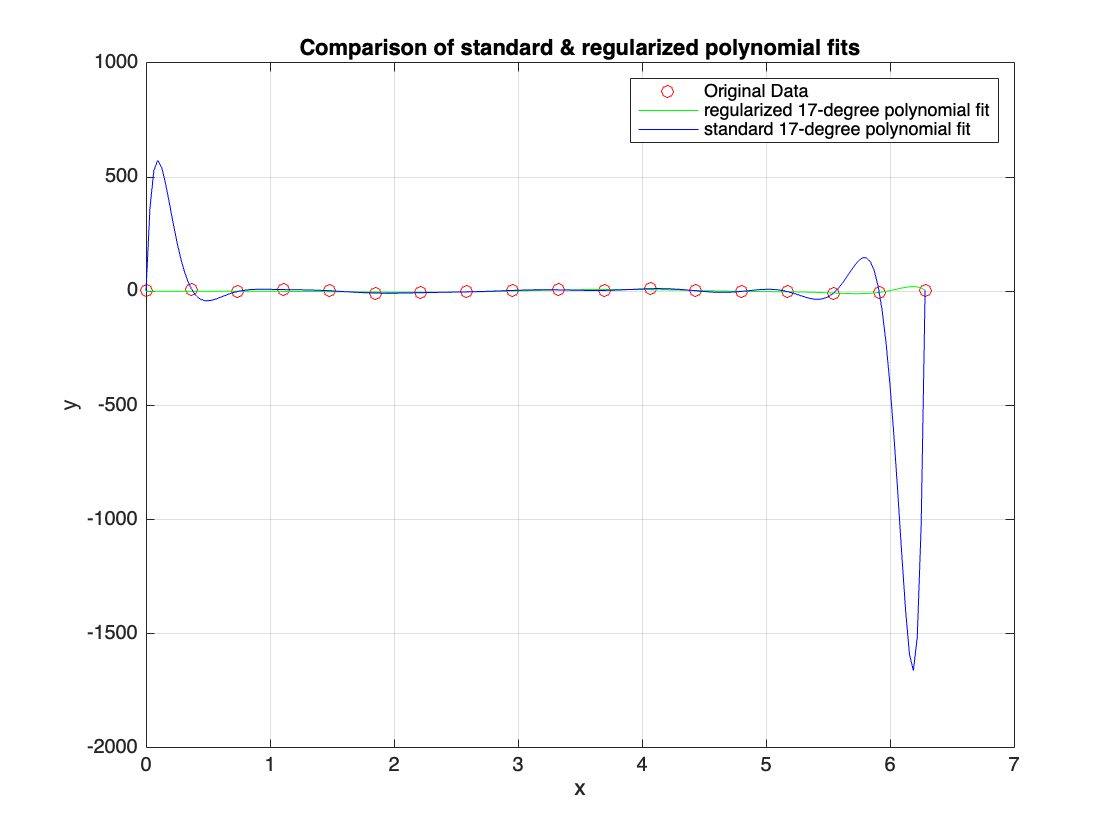

[Q_std, R_std] = qr(M, 0); % Non-regularized fit

qT_std = Q_std' * y; %  without regularization
R_upper_std = R_std(1:18, 1:18);
b_upper_std = qT_std(1:18);
Ar_std = backward_sub(R_upper_std, b_upper_std);
px_std = polyval(flipud(Ar_std), xv);

l = 100; % adjust lambda
y_augmented = [y; zeros(deg+1, 1)] ; % with regularization
M_augmented = [M; sqrt(l)*eye(18)] ;
[Q_reg, R_reg] = qr(M_augmented, 0);
qT_reg = Q_reg' * y_augmented;
bU_reg = qT_reg(1:18) ;
RU_reg = R_reg(1:18, 1:18);
Ar_reg = backward_sub(RU_reg, bU_reg);
px_reg = polyval(flipud(Ar_reg), xv) ;

figure;
plot(x, y, 'ro', 'DisplayName', 'Original Data');
hold on;
title('Comparison of standard & regularized polynomial fits');
plot(xv, px_reg, 'g-', 'DisplayName', 'regularized 17-degree polynomial fit ');
plot(xv, px_std, 'b-', 'DisplayName', 'standard 17-degree polynomial fit');
ylabel('y');
xlabel('x');
legend('show');
grid on;
hold off;

* % write your comments here for question 1 e*

    Since the standard polynomial fitting aims to pass through or extremely close to each data point, it is likely to have a more complicated curve with a larger variance. Large oscillations may arise from this, especially around the edges of the data range. Conversely, the regularized curve exhibits some overfitting. Because the regularization process penalizes the polynomial coefficients and essentially shrinks them towards zero, it should be smoother and less prone to big oscillations. This helps prevent overfitting by discouraging the model from growing overly complicated and fitting the training set too closely. Both curves show signs of extreme values at the edges.

f. The least squares regression is used to build the models based on the experimental data. As the new the new experimental data is available the obtained model must be updated. In this part, you will design an algorithm to update the model coefficients when new data is available. Similar to the previous parts we trying to fit the polynomial based model to the provided data.  Suppose we have  m-data points, we can write our Vandermonde matrix system as,


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
\vdots \\
y_m 
\end{array}\right\rbrack } }$$


Using the Normal equations, we know the least-square solution for the above system is given by


$${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}\;\mathit{\mathbf{a}}={\mathit{\mathbf{M}}}^T \mathit{\mathbf{y}}$$


In the following cell using the data provided in the file named, Asst3_data_Q1f.mat, fit the polynomial of order 2 using the Normal Equations. Use the matrix ${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}$explicitly, to compute the least square solution for the abovew system of equations. Choose the best algorithm to compute the solution.

load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 3/Asst3_data_Q1f.mat'); 
x = x_given;
y = y_given;

M = [ones(size(x)), x, x.^2];
result = (M' * M) \ (M' * y);
disp(result);

    1.2015
    0.9969
    1.0452



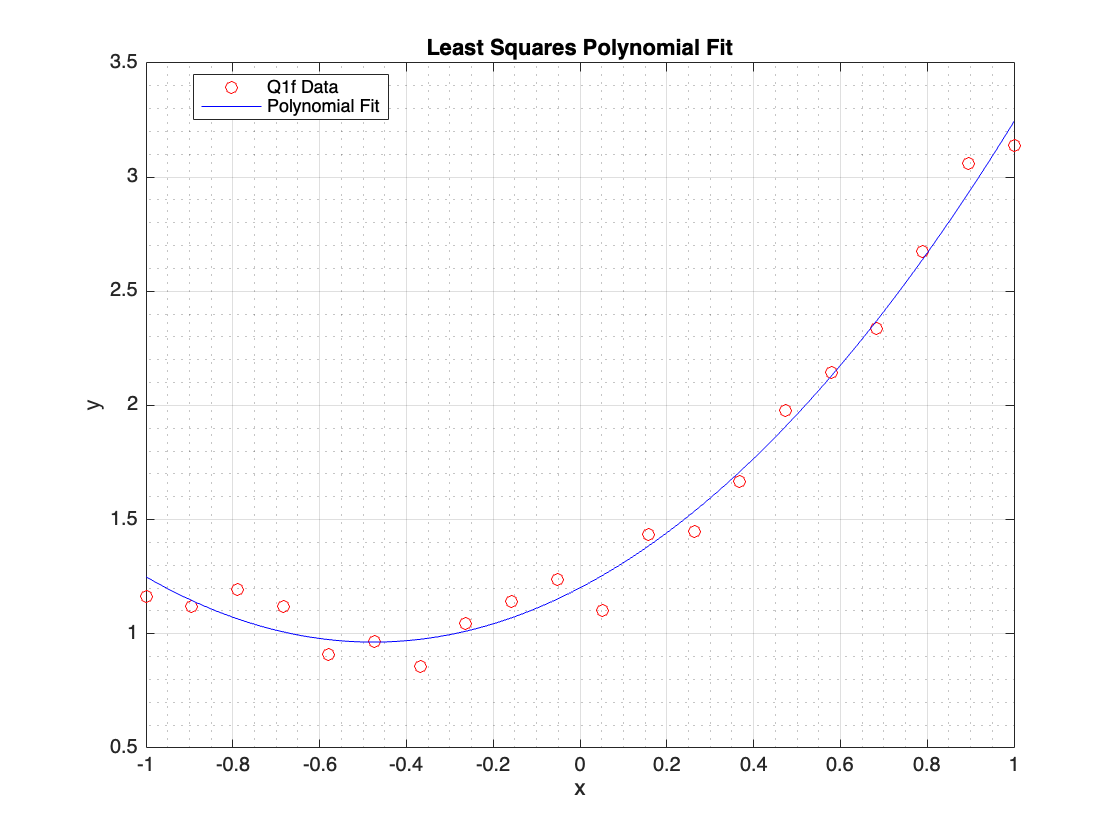

x_plot = linspace(min(x), max(x), 1000)';
M_plot = [ones(size(x_plot)), x_plot, x_plot.^2];
y_plot = M_plot * result;

figure;
plot(x, y, 'ro', 'DisplayName', 'Q1f Data');
hold on;
plot(x_plot, y_plot, 'b-', 'DisplayName', 'Polynomial Fit');
ylabel('y');
xlabel('x');
title('Least Squares Polynomial Fit');
legend('Location', 'best');
grid on; grid minor;

After running the experiment, we obtained a new data $y_{m+1}$ for input $x_{m+1}$, using this we can update the above system as,


$$\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_m  & x_m^2  & \cdots \; & x_m^n \\
1 & x_{m+1}  & x_{m+1}^2  & \cdots \; & x_{m+1}^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\hat{a} }_0 \\
{\hat{a} }_1 \\
\vdots \\
{\hat{a} }_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
\vdots \\
y_m \\
y_{m+1} 
\end{array}\right\rbrack$$


Note that in the above system the coefficients will be updated. The above system can also we written as,


$$\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \hat{\mathit{\mathbf{a}}} =\left\lbrack \begin{array}{c}
\mathit{\mathbf{y}}\\
y_{m+1} 
\end{array}\right\rbrack \;$$


where, ${\mathit{\mathbf{v}}}^T$ is a row vector containing the polynomials evaluated at the input point $x_{m+1}$, i.e.,  ${\mathit{\mathbf{v}}}^T =\left\lbrack \begin{array}{ccccc}
1 & x_{m+1}  & x_{m+1}^2  & \cdots  & x_{m+1}^n 
\end{array}\right\rbrack$ and $\hat{\mathit{\mathbf{a}}}$ is a column vector containing the updated coeffcients. 

x_mplus1 =  -3.1579e-01;
y_mplus1 =  1.5;

% form your vT vector
vT = [1, x_mplus1, x_mplus1^2];
disp(vT);

    1.0000   -0.3158    0.0997



We know how to obtain the least squares solutions for the above equation, we can construct the following normal equations,


$${\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \hat{\mathit{\mathbf{a}}} ={\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack }^{T\;} \left\lbrack \begin{array}{c}
\mathit{\mathbf{y}}\\
y_{m+1} 
\end{array}\right\rbrack$$


Upon multiplying the above matrices we get the following,


$$\left\lbrack \begin{array}{c}
{\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \;\hat{\mathit{\mathbf{a}}} =\left({\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{y}}+y_{m+1\;} \mathit{\mathbf{v}}\right)$$
 

Using the Sherman-Morrison formula, we can write the inverse of the matrix $\left(\mathit{\mathbf{B}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)$ as


$${\left(\mathit{\mathbf{B}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)}^{-1\;} =B^{-1\;} -\frac{{\mathit{\mathbf{B}}}^{-1\;} \mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \;{\mathit{\mathbf{B}}}^{-1} }{1+v^{T\;} {\mathit{\mathbf{B}}}^{-1} v}$$


Use the coefficeints ,$\mathit{\mathbf{a}}$ , which you already computed by solving ${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}\;\mathit{\mathbf{a}}={\mathit{\mathbf{M}}}^T \mathit{\mathbf{y}}$ and the Sherman-Morrison formula to compute the updated coefficients in $\;\hat{\mathit{\mathbf{a}}}$ without explicitly decomposing $\left({\mathit{\mathbf{M}}}^T \mathit{\mathbf{M}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)$or computing the inverse of $M^T M$. Implement your algorithm in the cell below.

% write your code here
M = [ones(length(x), 1), x, x.^2];
MTM = M' * M;
MTy = M' * y;
Bi = inv(MTM);
aHat = Bi * MTy;
newMTM = MTM + vT' * vT;
newMTy = MTy + vT' * y_mplus1;

newBi = Bi - (Bi * vT' * vT * Bi) / (1 + vT * Bi * vT');% Sherman-Morrison formula

newAHat = newBi * newMTy;
disp(newAHat);

    1.2460
    0.9770
    0.9874



## Question 2: **Nonlinear Equations for univariate case.**

a) Bisection Method is used for finding the roots of a continuous function, $f\left(x\right)$, given endpoints;$a,b$ with $f\left(a\right)\ldotp f\left(b\right)<0$ . The interval $\left\lbrack a\;\;b\right\rbrack$contains a root, $x_r$, because $f\left(a\right)$ and $f\left(b\right)$ have opposite signs.

Bisection method bisects the given interval at the midpoint, $c=\frac{a+b}{2}$ and then chooses a new interval based such that end of point of interval have opposite signs, i.e., if $f\left(a\right)\ldotp f\left(c\right)<0$, then the new interval is set to $\left\lbrack a\;\;c\right\rbrack$, else if $f\left(c\right)\ldotp f\left(b\right)<0$ then the interval is set to $\left\lbrack c\;\;b\right\rbrack$.

The above procedure is repeated until the following two conditions are simultaneously met, 

- The function value at the interval is sufficiently small, i.e., ${\left\|f\left(c\right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The new interval is sufficiently small, i.e., ${\left\|a-b\right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the Bisection Method in the cell below to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ in the interval $\left\lbrack -3\;\;\;0\right\rbrack \;$using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$. **Show the number of iterations the bisection method took to converge.**

Use the cell below to implement your code. 

Note: There is no need to write the function for Bisection Method. However, if you wish to implement the function, use the appendix.

%implement your bisection method here
f=@(x)x^4-2*x^2-4;
tol = 10^-5;
a = -3; 
b = 0;
[c,counter]= bisectionMethod(f,a,b,tol)

c = -1.7989

counter = 22

r = f(c);
disp(r)

   1.2621e-06



b) ** Newton-Raphson**

 Bisection Method requires the given function,$f\left(x\right)$ to be continuous, Newton-Raphson requires $f\left(x\right)$ to be continuous and differentiable. While the Newton- Raphson method converges faster than the bisection method, however, Newton-Raphson method does not guarantee convergence. Newton-Raphson works by linearising the $f\left(x\right)$, at the given initial guess, $x^{\left(0\right)}$as shown below


$$f\left(x\right)=f\left(x^{\left(0\right)} \right)+{f\left(x^{\left(0\right)} \right)}^{\prime } \left(x-x^{\left(0\right)} \right)$$


Setting the expression on the right to zero, provides an approximation to the root, and we obtain


$$x^{\left(1\right)} =x^{\left(0\right)} -\frac{f\left(x^{\left(0\right)} \right)}{{f\left(x^{\left(0\right)} \right)}^{\prime } }$$


Then, the function,$\;f\left(x\right)$, is again linearised using approximation,$x^{\left(1\right)}$as the initial guess, to obtain new approximation of the root. After $k$ iterations the new approximation for the root becomes,

  
$$x^{\left(k+1\right)} =x^{\left(k\right)} -\frac{f\left(x^{\left(k\right)} \right)}{{f\left(x^{\left(k\right)} \right)}^{\prime } }$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|f\left(x^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|\Delta x^{\left(k+1\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

where $\Delta x^{\left(k+1\right)} =$$x^{\left(k+1\right)} -x^{\left(k\right)}$.

Implement the **Newton-Raphson** Method in the cell below to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ use intial guess of $x^{\left(0\right)} =-3$ using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$.  If the convergence is not reached in 100 iterations, quit the algorithm by displaying an error message indicating that Newton-Raphson failed to converge. 

Plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$  for each iteration. 

% write your code here
f=@(x)x^4-2*x^2-4;
fderivative = @(x) 4*x^3-4*x; % derivative value
tol = 10^-5;
x0 = -3;
nmax = 100;

[x,deltaX] = newtonraphson(f,fderivative,x0,tol,nmax)

deltaX = -0.6146

deltaX = -0.3798

deltaX = -0.1705

deltaX = -0.0348

deltaX = -0.0013

deltaX = -1.9669e-06

x = -1.7989

deltaX =     0.6146
    0.3798
    0.1705
    0.0348
    0.0013
    0.0000


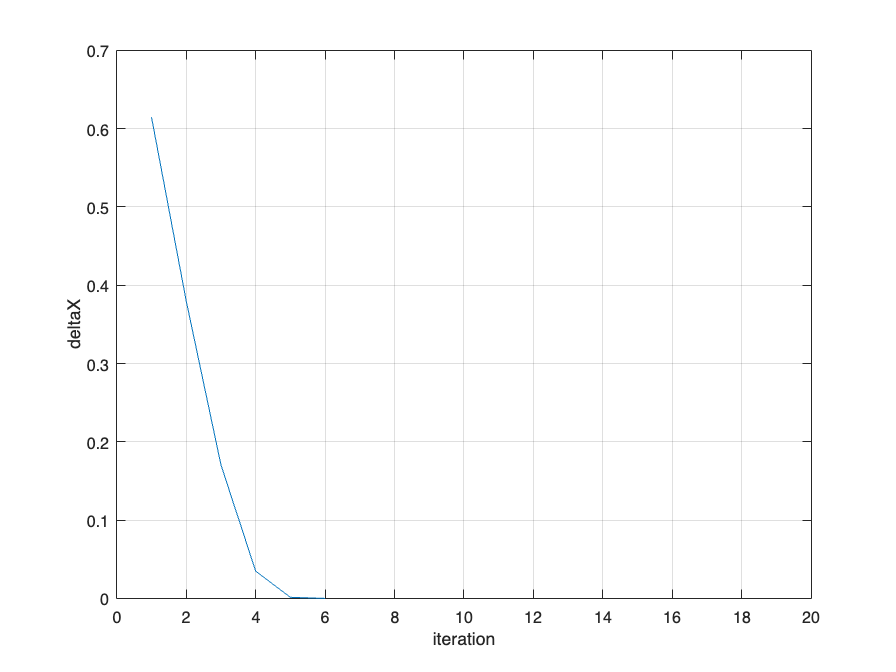

figure
plot(deltaX)
xlim ([0,20]);
ylabel('deltaX')
xlabel('iteration')
grid on;

## Question 3:  **Nonlinear Equations for N-variables.**

 Newton-Raphson Method can be used to solve the system of nonlinear equations of N-variables, $\left\lbrack x_1 ,\;x_2 ,\;\cdots ,\;x_n \right\rbrack$shown below,


$$f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$



$$f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$
 


$$\vdots$$



$$f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$


The above equations can be written as a vector valued function as shown below,


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
\vdots \\
f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)
\end{array}\right\rbrack$$


where $\mathit{\mathbf{X}}=\left\lbrack x_1 ,x_2 ,\cdots ,x_N \right\rbrack$ is the vector containing all the variables.

Following the idea of unidimensional Newton-Rapshson, we start with an initial guess ${\mathit{\mathbf{X}}}^{\left(0\right)}$ and we use this to linearise the function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)$ around${\;\mathit{\mathbf{X}}}^{\left(0\right)}$ 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\;$$

$$f\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)+\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)\right)\left(\mathit{\mathbf{X}}-{\mathit{\mathbf{X}}}^{\left(0\right)} \right)$$


Setting the expresson on the left side to zero, we find the approximation of the solution vector. After $k$ iterations the approximation for the solution vector can be written as 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


where $\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$ is the vector valued function evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$ and $\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$ is the jacobian evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$. The structure of the Jacobian is given by,


$$\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \cdots  & \frac{\partial f_1 }{\partial x_n }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \cdots  & \frac{\partial f_2 }{\partial x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_n }{\partial x_1 } & \frac{\partial f_n }{\partial x_2 } & \cdots  & \frac{\partial f_n }{\partial x_n }
\end{array}\right\rbrack$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Find a solution of the following system of three nonlinear equations using Newton-Raphson method.


$${9x}_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 \;=3$$



$$x_{1\;}^{2\;} +\;{2x}_2^2 -x_{3\;} =2$$



$$x_{1\;} +x_{2\;} +12x_3 =5$$


Note that this can be expressed as 

$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
{9x}_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 -3\\
x_{1\;}^{2\;} +\;{2x}_2^2 -x_{3\;} -2\\
x_{1\;} +x_{2\;} +12x_3 -5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$,        where $\mathit{\mathbf{X}}={\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack }^T$

a) Write a MATLAB function named *evaluateEquations(x)*, that evaluates the above equation at a given input vector. Use the provided $\mathit{\mathbf{X}}$ to check your implementation.

Use the framework of the function provided in the Appendix. 

% X in this case is an example
 
X = [2;3;4];

f  = evaluateEquations(X)

f =     58
    16
    48



disp(f);

    58
    16
    48



b) Write a MATLAB function named *evaluateJacobian()*, that evaluates the Jacobian of the above equations. Use the provided $\mathit{\mathbf{X}}$ to check your implementation.

Use the framework of the function provided in the Appendix.  

X = [2;3;4];
J  = evaluateJacobian(X)

J =     36     6     8
     4    12    -1
     1     1    12



disp(J);

    36     6     8
     4    12    -1
     1     1    12



**Newton-Raphson **

c) Implement the Newton-Raphson method, use the function named *NewtonRaphson() *to write the code for this. 

Start with intial guess, $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack }^T$  and then find a suitable intial guess. Plot the 2-Norm of difference between consecutive solutions ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2$ for each iteration. 

Use the framework of the function provided in the Appendix.  In the  *NewtonRaphson() *function use the methods implemented in part (a) and (b).

Xguess = [0 0 0]; % startinginitial guess 
% write your code here

Xguess = [0; 1; 1]; % update guess
fu = @evaluateEquations;
Ja = @evaluateJacobian ;
[X,deltaX] = NewtonRaphson(fu,Ja,Xguess,1e-5)

X =    -0.4448
    1.0414
    0.3670


deltaX =    10.7061    5.3628    2.6717    1.3171    0.6229    0.2521    0.0614    0.0041    0.0000    0.0000


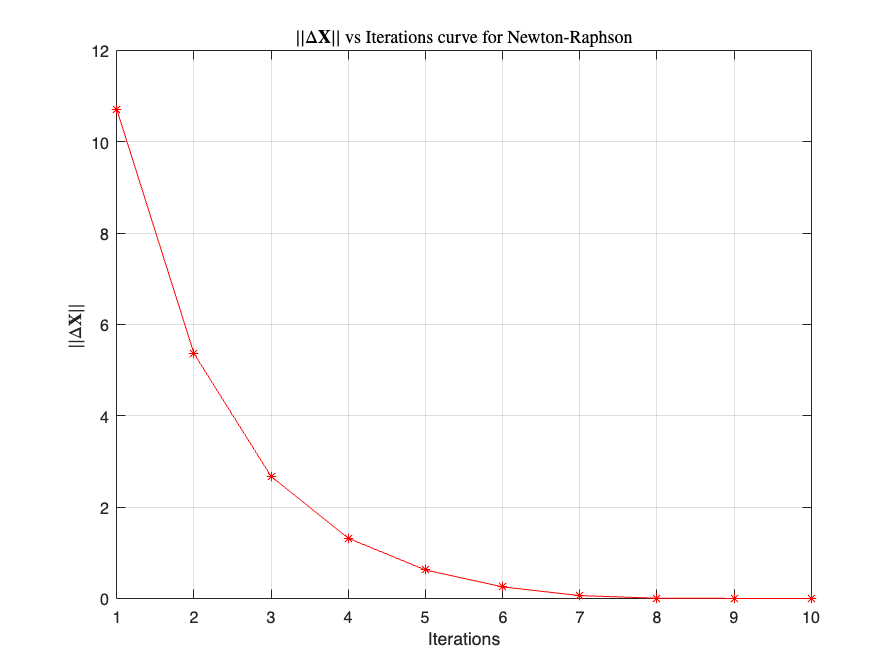


plot(deltaX,'r-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  vs Iterations curve for Newton-Raphson', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Jacobian**

d) Suppose you do not have access to the Jacobian of  the nonlinear eqautions, use the Broyden's method  to compute/ update the Jacobian.  

At the $(k+1)^{th}$ iteration of Newton Raphson, the soltuion vector $\mathit{\mathbf{X}}$  is given by 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


let, $J_{k\;} =\;\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$. Using the Broyden's update, $J_{k\;}$ can be computed as 


$$J_{k\;} =J_{k-1} +\;\frac{\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;-\;\;J_{k-1} \;\;\left({\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \right)\;}{{\left\|\;\;\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\;\right)\;\;\right\|}_2^{2\;} }{\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\right)}^T$$


Write a MATLAB function named* NR_Broyden_Jacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for Jacobian $J_0  =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.

Use the framework of the function provided in the Appendix

func = @evaluateEquations;
[Xout,deltaXBroyden]  = NR_Broyden_Jacobian(func, Xguess,1e-5)

Xout =    -0.4448
    1.0414
    0.3670


deltaXBroyden =     8.1240    8.3979   21.2965   22.4406    7.5517    9.4631   41.8731   42.4471    9.7077   13.2335    1.7631    2.2148    1.1670    0.8683    0.6101    0.4660    0.3826    0.4029    3.6825    3.7525    0.0613    0.3406    0.9384    1.0282    0.0716    0.2188    0.2062    0.5081    1.5532    1.6597    0.1656    0.3675    0.1102    0.1448    0.1277    1.0809    1.1088    0.0275    0.3248    0.6242    0.8516    2.6154    2.6578    0.0374    0.1052    0.0345    1.3783    1.4708    0.3695    0.6775


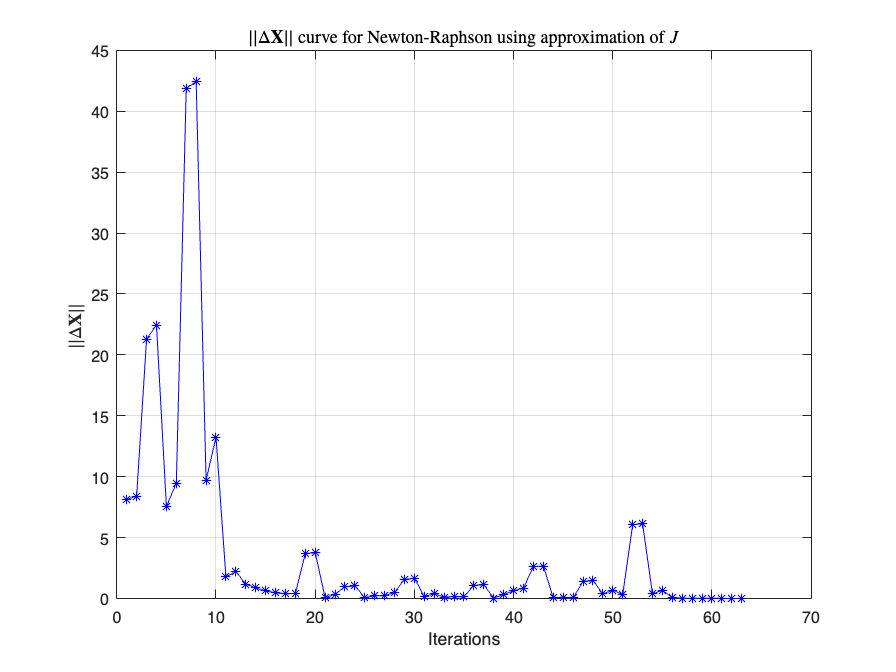

plot(deltaXBroyden,'b-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J$', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Inverse of Jacobian**

e)  In part d) , you implemented the Broyden's method for updating the Jacobian, in this part use the Broyden's update for computing inverse of Jacobian. The inverse of Jacobian can be computed as 


$$J_{k\;}^{-1} =J_{k-1}^{-1} +\;\frac{\;\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)-\;J_{k-1}^{-1\;} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;}{{\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} J_{k-1}^{-1} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)}\left({\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} \;J_{k-1}^{-1} \right)$$


Write a MATLAB function named* NR_Broyden_InvJacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for inverse of Jacobian $J_0^{-1} =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.

Use the framework of the function provided in the Appendix.

func =@evaluateEquations;
Xguess = [0; 1; 1]; % update guess
[Xout,count,deltaXBroyden]  = NR_Broyden_InvJacobian(func, Xguess,1e-5)

Xout =    -0.4448
    1.0414
    0.3670


count = 61

deltaXBroyden =     8.1240    8.3979   21.2965   22.4406    7.5517    9.4631   41.8731   42.4471    9.7077   13.2335    1.7631    2.2148    1.1670    0.8683    0.6101    0.4660    0.3826    0.4029    3.6825    3.7525    0.0613    0.3406    0.9384    1.0282    0.0716    0.2188    0.2062    0.5081    1.5532    1.6597    0.1656    0.3675    0.1102    0.1448    0.1277    1.0808    1.1087    0.0275    0.3246    0.6250    0.8506    2.4611    2.5052    0.0377    0.0994    0.0341    2.0498    2.1190    0.3268    0.6675


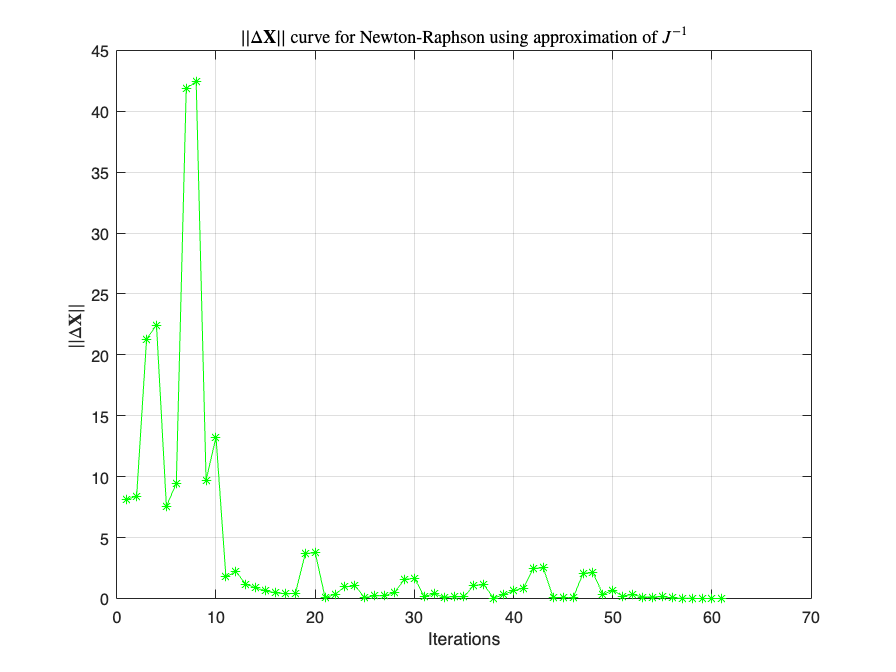

plot(deltaXBroyden,'g-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J^{-1}$', 'Interpreter', 'latex')

f)  Given a nonlinear system with $n$ number of nonlinear equations, shown below,


$$f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;=3x_{1\;} -2x_{1\;}^2 -2x_{2\;} +1=0$$



$$f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;\;=3x_{i\;} -2{x_i }_{\;}^2 -x_{i-1} -2x_{i+1} +1=0,\;\;\;\;\;\textrm{for}\;\;\;1<i<n$$


 
$$f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)=3x_{n\;} -2{x_n }_{\;}^2 -x_{n-1} +1=0$$


where, $x_1$, $x_2$, ..., $x_n$  are the variables. 

The nonlinear vector of equations can written as, 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
f_2 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


The Matlab function to evalaute the above function is named *nlfunction() *and  it is  provided to you in appendix. 

Suppose you  do not have access to the jacobian, so you chose to solve the above nonlinear function using Broyden's methods you developed in part (d) and (e). The code cell below uses the Broyden's algorithms you implemented in paer d) and  e) to solve the above nonlinear system for different size of the system ranging from  $10\le n\le 200$. 

Run the cell below and explain the results in Figure Question 3 f.

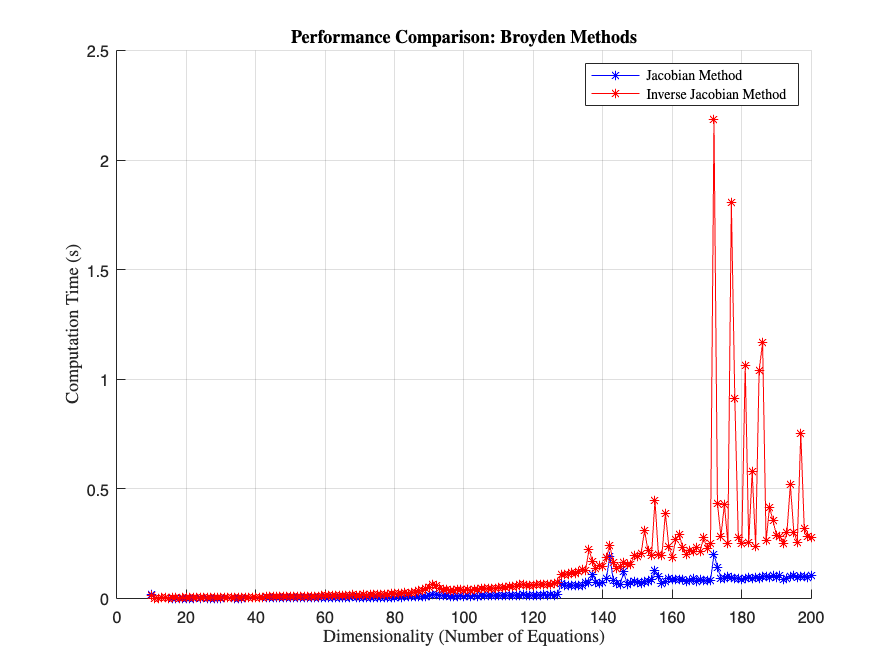

clear all
func1 = @nlfunction;
N = 200; 
c = 1; 
time_BroydenIJ = zeros(N-10+1,1);
time_BroydenJ = zeros(N-10+1,1);

for index = 10:N
    initialEstimate = zeros(index,1);
    
    inverseJacobianStart = tic;
    [solutionInverse, ~] = NR_Broyden_InvJacobian(func1, initialEstimate, 1e-6) ;
    time_BroydenIJ(c) = toc(inverseJacobianStart);  
    jacobianStart = tic ; 
    [solutionJacobian, ~] = NR_Broyden_Jacobian(func1, initialEstimate, 1e-6);
    time_BroydenJ(c) = toc(jacobianStart);   
    c = c + 1;
end

figure();
clf;
hold on;

plot(10:N, time_BroydenIJ, 'b-*'); % Time for inverse Jacobian
plot(10:N, time_BroydenJ, 'r-*');  % Time for Jacobian

title('\textbf{Performance Comparison: Broyden Methods}', 'Interpreter', 'latex');
legend('Jacobian Method', 'Inverse Jacobian Method', 'Interpreter', 'latex');
ylabel('Computation Time (s)', 'Interpreter', 'latex');
xlabel('Dimensionality (Number of Equations)', 'Interpreter', 'latex');
grid on; 

% Write your explanation here 

    The graph compares how long it takes for two distinct Broyden's approaches to solve a system of nonlinear equations of varied sizes. The Broyden's approach that directly approximates the Jacobian (J) is represented by red stars, whereas the method that approximates the inverse Jacobian is represented by blue stars. The demonstration between these two Broyden approximations within the same range implies that the approximation of inverse Jacobian is much less costly than the Jacobian one since it reduces the numerical errors through computation of inverse of matrices.

## **Question 4:  Eigenvalues**

The Power Iteration method is used to compute the dominant eigen value  and the  eigen vector associated with the  dominant eigen value of a given matrix. Any random vector $x_0$ can be written as the linear combination of $n$ independent eigen vectors of a matrix ${\mathit{\mathbf{A}}}_{n\times n}$ as 


$${\mathit{\mathbf{x}}}_{0\;} =c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\mathit{\mathbf{v}}}_2 +\cdots +c_n {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;} \;\;\;$$
                                             
$$\left(1\right)$$


On multiplying the above with matrix $\mathit{\mathbf{A}}$ we get,


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\mathit{\mathbf{A}}\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;}$$
                                  
$$\left(2\right)$$


The vectors ${\mathit{\mathbf{v}}}_i$'s are the eigen vectors of matrix $\mathit{\mathbf{A}}$, therefore, $\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}} =\lambda_{i\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$. The symbol  $\lambda_{i\;}$denotes the eigen value corresponding to eigen vector ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$.  


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;} \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                                
$$\left(3\right)$$


Equation (3), can be  generalised to 


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;}^{k\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;}^k \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;}^{k\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                              
$$\left(4\right)$$


Without loss of generality (4) can be written as


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =\lambda_{1\;}^{k\;} \left(c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\frac{\lambda_{2\;}^k }{\lambda_{1\;}^{k\;} }\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \frac{\lambda_{n\;}^{k\;} }{\lambda_{1\;}^{k\;} }{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;} \right)$$
                     
$$\left(5\right)$$


Assuming that $\left|\lambda {\;}_1 \right|>$$\left|\lambda_2 \right|>\cdots \left|\lambda_n \right|$.  As $k\to \infty$, the terms with  $\frac{\lambda_{j\;}^k }{\lambda_{1\;}^{k\;} }\to 0$.  Thus, as $k\to \infty$,  ${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;}$converges to the eigen vector ${\mathit{\mathbf{v}}}_{1\;}$ corresponding to the largest eigen value. Write an iterative algorithm which computes the eigen vector and eigen value using the following recurssive formula,


$${\mathit{\mathbf{v}}}^{\left(k+1\right)} =\;\frac{\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} }{\parallel \mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel }$$
                                                                   
$$\left(6\right)$$
   

where ${\mathit{\mathbf{v}}}^{\left(k+1\right)}$ is the eigen vector at ${\left(k+1\right)}^{\textrm{th}}$iteration.

 Stop the algorithm using when the $\parallel {\mathit{\mathbf{v}}}^{\left(k+1\right)} \;-{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel \;<\epsilon_{\textrm{tol}}$, where $\epsilon_{\textrm{tol}}$ is the input tolerance value. 

Write a MATLAB function power_method(A,tol) that uses power iteration algorithm to compute the dominant eigen value and the eigenvector. 

Use the cell below to test the your function, you can use MATLAB's built in function, eig (see MATLAB documentation) to compare your answers.

M = randi(15,5)/10;
A = M'* M;
[e,v]= power_method(A,1e-4);

[eig_vectors_a,eig_values_a] = eig(A) ;
[max_eig_val, i] = max(diag(eig_values_a)) ;
true_eig_vector = eig_vectors_a(:, i);
disp('eigenvalue: ') ;

eigenvalue: 


disp(e);

   27.4875



disp(['eigenvector: ']);

eigenvector: 


disp(v);

    0.4271
    0.4345
    0.4672
    0.4658
    0.4399



disp('maximum eigenvalue: ');

maximum eigenvalue: 


disp(max_eig_val);

   27.4875



disp('true eigenvector:');

true eigenvector:


disp(true_eig_vector);

    0.4271
    0.4345
    0.4672
    0.4658
    0.4399



# Appendix

Question 1 a)

## *Implement Polynomial Matrix here *

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
    M = ones(length(x), n+1);

    for i = 1:n
        M(:, i+1) = x.^i;
    end
end

% forward and backward substitution functions from Assignment 1
function y = forward_sub(L,b)
% y is the vector
% L is the lower triangular matrix
    n = length(b);
    y = zeros(n,1);
    for i = 1:n
        y(i) = ( b(i) - L(i, 1: i-1) * y(1:i-1) ) / L(i,i);
    end
end 

function x = backward_sub(R, b)
    % X is the vector
    % U is the upper triangular matrix
    n = length(b);
    x = zeros(n, 1); % Preallocate space for the solution vector x

    for i = n:-1:1
        x(i) = (b(i) - R(i, i+1:n) * x(i+1:n)) / R(i, i);
    end
end

Function provided for Question 1 part e)

function [F] = nlfunction(x)
% x is a colmns vecotr.
% Evaluate the vector function

z = length(x);
F = zeros(z,1);
i = 2:(z-1);
F(i) = (3-2*x(i)).*x(i)-x(i-1)-2*x(i+1) + 1;
F(z) = (3-2*x(z)).*x(z)-x(z-1) + 1;
F(1) = (3-2*x(1)).*x(1)-2*x(2) + 1;

end

Question 2) a)

function [x, iterations] = bisectionMethod(f,a,b,tol)

% inputs :
% f is  the function 
% ( it is supplied as a handle for the nonlinear  fucniton f)
% in the Q2b it the fiunction f is already defined for you


% a and b: specify the interval
% tol is the desired tolerance 



%outputs:
% x : is the solution of the nonlinear equation
% iterations is thenumber of iterations your method took to converge.


% write your code here 
    iterations = 0;
    c = (a + b) /2;
    while abs(b-a) >= tol || abs(f(c)) >= tol
        iterations = iterations + 1;
        c = (a+b)/2;
        if (abs(b-a) < tol) && abs(f(c)) < tol
            break;
        elseif f(a)*f(c) < 0
            b = c;
        else
            a = c;
        end 
    end
    x = c;

end

Question 2 b)

function [z,normdeltaX]=newtonraphson(f,fderiv,x0,tol,itermax)

% inputs :
% f is  the function 
% ( it is supplied as a handle for the nonlinear  fucniton f)
% in the Q2b it the fiunction f is already defined for you

%fderiv is  the derivative of nonlinear function 
% ( it is supplied as a handle for the nonlinear  fucniton f)

% x0 is the initial guess
% tol is the desired tolerance 
% itermax is the maximum number of iterations


%outputs:
% x : is the solution of the nonlinear equation
%normdeltaX is the norm of deltaX at each iteration


% write your code here 
    z = x0;
    normdeltaX = [];
    for iter = 1: itermax
        deltaX = f(z)/fderiv(z) 
        z = z - deltaX;

        normdeltaX = [normdeltaX; abs(deltaX)] ;
        if (abs(f(z)) < tol && abs(deltaX) < tol)
            break; 
        end
    end

    if (iter == itermax && ((abs(f(z))) >= tol || abs(deltaX) >= tol) )
        error('Failed to converge')
    end
end


Question 3) a)

function f  = evaluateEquations(x)

 f = zeros(3,1);
 % write your code here 
    f(1) = 9*x(1)^2 + x(2)^2 + x(3)^2 - 3;
    f(2) = x(1)^2 + 2*x(2)^2 - x(3) - 2;
    f(3) = x(1) + x(2) + 12*x(3) - 5;

end 


Question 3) b)

function J  = evaluateJacobian(x)
   J = zeros(3,3);
   
   % write your code here
   %partial derivatives
   J(1,1) = 18*x(1);  % ∂(f1)/∂x1
   J(1,2) = 2*x(2);   % ∂(f1)/∂x2
   J(1,3) = 2*x(3);   % ∂(f1)/∂x3
    
   J(2,1) = 2*x(1);   % ∂(f2)/∂x1
   J(2,2) = 4*x(2);   % ∂(f2)/∂x2
   J(2,3) = -1;       % ∂(f2)/∂x3
    
   J(3,1) = 1;        % ∂(f3)/∂x1
   J(3,2) = 1;        % ∂(f3)/∂x2
   J(3,3) = 12;       % ∂(f3)/∂x3
end

Question 3) c)

function [Xout,normDeltaX]  = NewtonRaphson(func,Jac,Xguess,tol)
% func is the handle for evaluateEquations().. it is created for you
% Jac i is the handle for evaluateJacobian().. it is created for you

% Xguess is the initial Guess vector :
% tol is the desired tolerance

% Xout is the ouput vector
% normDeltaX stores the norm of the deltaX at each iteration

% write your code here
   % Initialize variables
    Xout = Xguess;
    normDeltaX = [];
    iter = 0;
    max = 100; 
    for i = 1:max
        f_val = func(Xout);
        J_val = Jac(Xout);

        deltaX = -J_val\f_val;
        Xout = Xout + deltaX;
        normDeltaX(end+1) = norm(deltaX);
        if ( (norm(deltaX) < tol) && (norm(f_val) < tol) )
            break;
        end
        if (i >= max)
            error('Failed to converge.');
        end
    end
end

Appendix: Question 3 d)

function [Xout,normDeltaX]  = NR_Broyden_Jacobian(func, Xguess,tol)
% func is the handle for evaluateEquations().. it is created for you
% Xguess is a Column Vector , it is the initial Guess vector :
% tol is the desired tolerance

% Xout is the ouput vector
% normDeltaX stores the norm of the deltaX at each iteration


J = eye(size(Xguess,1)); %keep this line

% write your code here
    deltaX = inf; %initialization above tol
    normDeltaX = [] ;
    X = Xguess;
    f_val = func(X);
    while norm(deltaX) > tol && norm(f_val) > tol
        f_val = func(X);
        deltaX = -J\f_val;
        newX = X + deltaX ;
        normDeltaX(end+1) = norm(deltaX) ;

        deltaF = func(newX) - f_val;
        J = J + (deltaF - J * deltaX) * (deltaX') / (deltaX' * deltaX);
        X = newX;
    end
    Xout = X;
end

Appendix: Question 3 e)

function [Xout,count,normDeltaX]  = NR_Broyden_InvJacobian(func, Xguess,tol)
%func is the handle for evaluateEquations().. it is created for you
% Xguess is a Column Vector , it is the initial Guess vector :
% tol is the desired tolerance

% Xout is the ouput vector
% normDeltaX stores the norm of the deltaX at each iteration


J = eye(size(Xguess,1)); %keep this line

% write your code here
    count = 0;
    X = Xguess;
    deltaX = inf;
    normDeltaX = [];
    f_val = func(X);
    while ( ( tol < norm(f_val) ) && (norm(deltaX) > tol ) )
        count = count + 1;
        f_val = func(X) ;
        deltaX = -J * f_val;
        newX = X + deltaX;

        normDeltaX(end+1) = norm(deltaX) ;
        deltaF = func(newX) - f_val;
        J = J + (deltaX-J*deltaF)*(deltaX'*J) / (deltaX'*J*deltaF);
        X = newX;
    end
    Xout = X;
end

 Appendix Question 4

function [eig_val,eig_vector]=  power_method(A,tol)
% Find the largest eigen value forthe input matrix and the eigen vector
% associated with it.
% Input : A is the matrix 
%         tol is the tolerance
% Output:
% eig_val is the largest eigen values 
% eig_vector is the eigen vector associsted with the larges eigen value
    n = size(A, 1);
    eig_vector = rand(n,1);
    eig_vector = eig_vector / norm(eig_vector);
    eig_val = 0;
    error = inf;
    while abs(error - eig_val) > tol
        eig_vector = A*eig_vector;
        eig_vector = eig_vector/ norm(eig_vector);
        error = eig_val;
        eig_val = eig_vector' * A * eig_vector;
    end
end